# Processing LL2 data and producing plots

### Preamble

clc
clear
close all


### Plot figures

plotFigs=true;

### Import Data

load("data/Launches.mat")
load("data/Agencies.mat")
load("data/Pads.mat")
load("data/Locations.mat")
load("data/Orbits.mat")
load("data/Statuses.mat")

### Launches Data

LaunchName=strings(1,length(Launches));
LaunchStatus=NaN(1,length(Launches));
LaunchT0=NaT(1,length(Launches));
LaunchLSP=NaN(1,length(Launches));
LaunchCountry=strings(1,length(Launches));
LaunchOrbit=NaN(1,length(Launches));
LaunchPad=NaN(1,length(Launches));
LaunchProgram=NaN(1,length(Launches));

for ii=1:length(Launches)
    LaunchName(ii)=string(Launches(ii).name);
    LaunchStatus(ii)=Launches(ii).status.id;
    LaunchT0(ii)=datetime(Launches(ii).net,'Format','yyyy-MM-dd''T''HH:mm:ss''Z''');
    LaunchLSP(ii)=Launches(ii).launch_service_provider.id;
    LaunchCountry(ii)=Launches(ii).pad.location.country_code;
    if ~isempty(Launches(ii).mission)
        if ~isempty(Launches(ii).mission.orbit)
            LaunchOrbit(ii)=Launches(ii).mission.orbit.id;
        end
    end
    LaunchPad(ii)=Launches(ii).pad.id;
    if ~isempty(Launches(ii).program)
        LaunchProgram(ii)=Launches(ii).program.id;
    end 
end

### Locations table

jj=0;
for ii=1:length(Locs)
    if isempty(Locs(ii).pads)
        continue
    end
    jj=jj+1;
    LocsName(jj)=string(Locs(ii).name);
    LocsLat(jj)=str2double(Locs(ii).pads(1).latitude);
    LocsLong(jj)=str2double(Locs(ii).pads(1).longitude);
    LocsCount(jj)=Locs(ii).total_launch_count;
end

### Return if no plots

if ~plotFigs
    return
end

### Figures

Location Map

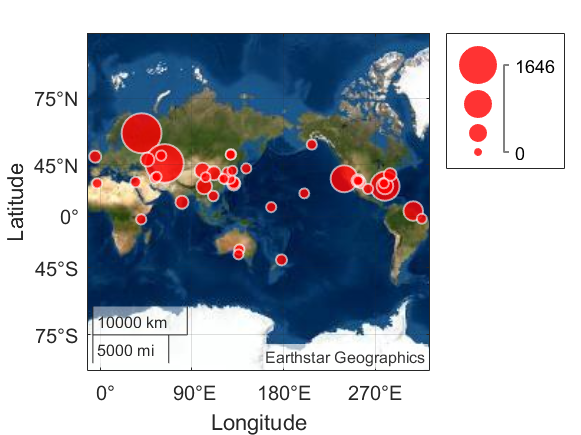

figure
geobubble(LocsLat,LocsLong,LocsCount,'BubbleColorList',[1 0 0])
geobasemap('satellite')

Launch attemps per launch country

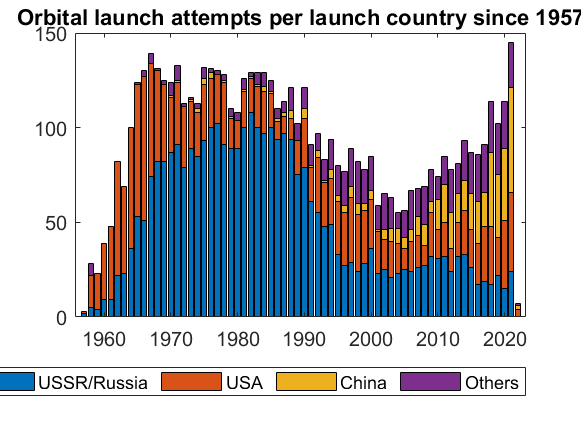

figure
[N1,edges] = histcounts(year(LaunchT0((LaunchT0<datetime('now')).*(LaunchOrbit~=15).*(LaunchCountry=='RUS' | LaunchCountry=='KAZ')>=1)),min(year(LaunchT0(LaunchT0<datetime('now')))):(year(datetime('now'))+1));
[N2,edges] = histcounts(year(LaunchT0((LaunchT0<datetime('now')).*(LaunchOrbit~=15).*(LaunchCountry=='USA')>=1)),min(year(LaunchT0(LaunchT0<datetime('now')))):(year(datetime('now'))+1));
[N3,edges] = histcounts(year(LaunchT0((LaunchT0<datetime('now')).*(LaunchOrbit~=15).*(LaunchCountry=='CHN')>=1)),min(year(LaunchT0(LaunchT0<datetime('now')))):(year(datetime('now'))+1));
[N4,edges] = histcounts(year(LaunchT0((LaunchT0<datetime('now')).*(LaunchOrbit~=15).*(LaunchCountry~='USA' & LaunchCountry~='RUS' & LaunchCountry~='KAZ' & LaunchCountry~='CHN')>=1)),min(year(LaunchT0(LaunchT0<datetime('now')))):(year(datetime('now'))+1));
bar(edges(1:(end-1)),[N1',N2',N3',N4'],'stacked','EdgeColor','black','LineWidth',0.001)
legend("USSR/Russia","USA","China","Others",'Location','southoutside','Orientation','horizontal')
title('Orbital launch attempts per launch country since 1957')
ylim([0 150])
exportgraphics(gcf,'plots/OrbitalAttemptsPerCountry.pdf')
exportgraphics(gcf,'plots/OrbitalAttemptsPerCountry.png','Resolution',300)

Launch attemps per launch country STACKED

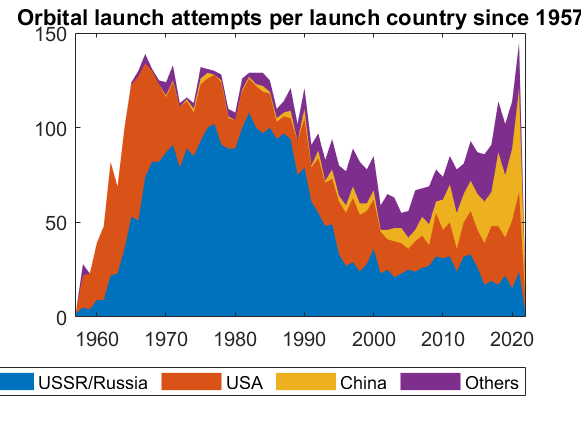

figure
area(edges(1:end-1),[N1',N2',N3',N4'],'EdgeColor','none','LineWidth',0.001)
legend("USSR/Russia","USA","China","Others",'Location','southoutside','Orientation','horizontal')
title('Orbital launch attempts per launch country since 1957')
ylim([0 150])
xlim([1957 year(datetime('now'))])
exportgraphics(gcf,'plots/OrbitalAttemptsPerCountryStacked.pdf')
exportgraphics(gcf,'plots/OrbitalAttemptsPerCountryStacked.png','Resolution',300)

Successful orbital launches per launch country

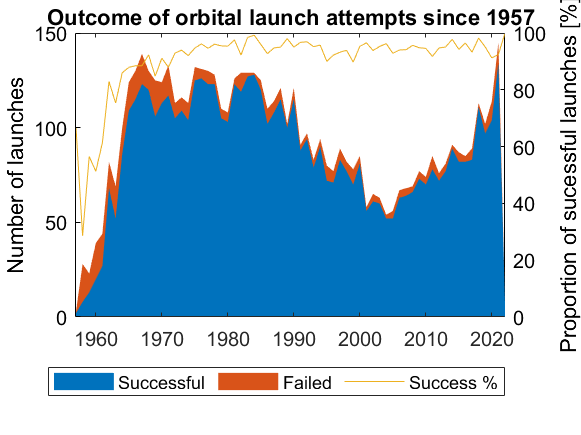

figure
[N1,edges] = histcounts(year(LaunchT0(LaunchStatus==3.*(LaunchT0<datetime('now')).*(LaunchOrbit~=15))),min(year(LaunchT0(LaunchT0<datetime('now')))):(year(datetime('now'))+1));
[N2,edges] = histcounts(year(LaunchT0(LaunchStatus==4.*(LaunchT0<datetime('now')).*(LaunchOrbit~=15))),min(year(LaunchT0(LaunchT0<datetime('now')))):(year(datetime('now'))+1));
area(edges(1:end-1),[N1',N2'],'EdgeColor','none','LineWidth',0.001)
ylim([0 150])
ylabel('Number of launches')
hold on
yyaxis right
plot(edges(1:end-1),100*N1./(N1+N2))
ax = gca;
ax.YColor = 'black';
ylim([0 100])
ylabel('Proportion of sucessful launches [%]')
legend("Successful","Failed","Success %",'Location','southoutside','Orientation','horizontal')
title('Outcome of orbital launch attempts since 1957')
xlim([1957 year(datetime('now'))])
exportgraphics(gcf,'plots/OutcomeOrbitalAttemptsStacked.pdf')
exportgraphics(gcf,'plots/OutcomeOrbitalAttemptsStacked.png','Resolution',300)